Ecuaciones submarino.

clear, clc
close all
x=@(x,y) x;
y=@(x,y) y;
z=@(x,y) (6-2*y^2)^0.5;

x1=@(x,y) x;
y1=@(x,y) y;
z1=@(x,y) -(6-2*y^2)^0.5;

x2=@(x,y) x;
y2=@(x,y) y;
z2=@(x,y) -((-2*x-2*y^2+12))^0.5;

x3=@(x,y) x;
y3=@(x,y) y;
z3=@(x,y) ((-2*x-2*y^2+12))^0.5;

x4=@(x,y) x;
y4=@(x,y) y;
z4=@(x,y) (2*x-2*y^2+12)^0.5;

x5=@(x,y) x;
y5=@(x,y) y;
z5=@(x,y) -(2*x-2*y^2+12)^0.5;

R=0;
G=0;
B=0;

figure(1)
fmesh(x,y,z,[-3 3],"EdgeColor",[R G B])

hold on
fmesh(x1,y1,z1,[-3 3],"EdgeColor",[R G B])

fmesh(x2,y2,z2,[3 6 -4 4],"EdgeColor",[R G B])

fmesh(x3,y3,z3,[3 6 -4 4],"EdgeColor",[R G B])

fmesh(x4,y4,z4,[-6 -3 -4 4],"EdgeColor",[R G B])

fmesh(x5,y5,z5,[-6 -3 -4 4],"EdgeColor",[R G B])

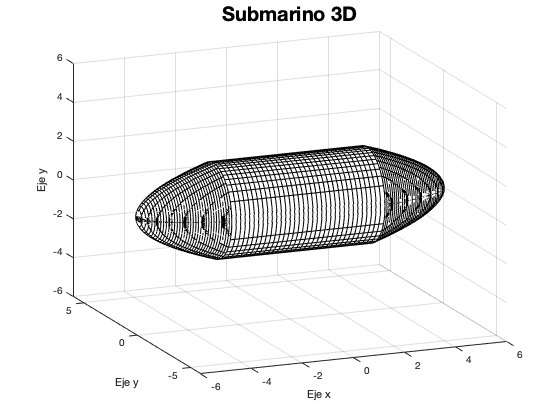


xlabel('Eje x')
ylabel('Eje y')
zlabel('Eje y')

title('Submarino 3D',"FontSize",20)

xlim([-6 6])
ylim([-6 6])
zlim([-6 6])

view([-22.60 19.83])

hold off

saveas(figure(1),'sumbarino3D','jpg')

figure(2)
fmesh(x,y,z,[-3 3],"EdgeColor",[R G B])

hold on
fmesh(x1,y1,z1,[-3 3],"EdgeColor",[R G B])

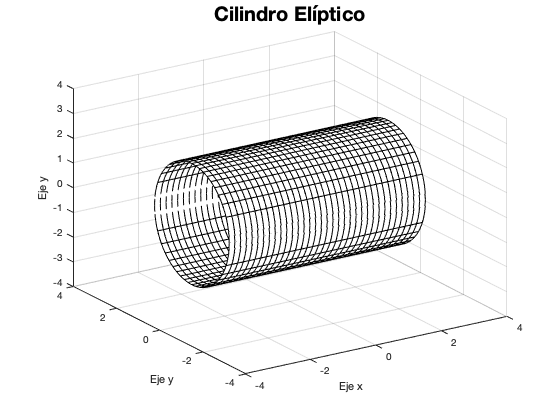

xlabel('Eje x')
ylabel('Eje y')
zlabel('Eje y')
title('Cilindro Elíptico',"FontSize",20)
xlim([-4 4])
ylim([-4 4])
zlim([-4 4])
view([-33.36 27.89])
hold off
saveas(figure(2),'Cilindro','jpg')

figure(3)
fmesh(x2,y2,z2,[3 6 -4 4],"EdgeColor",[R G B])

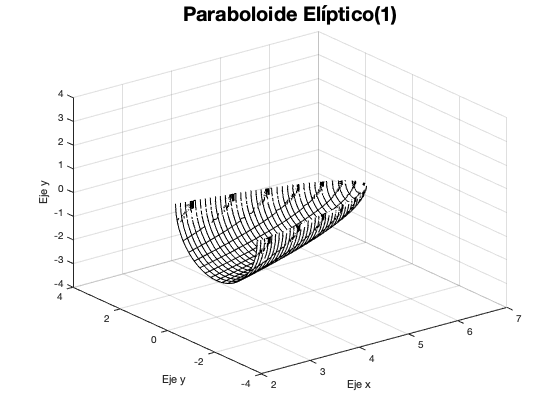

hold on
fmesh(x3,y3,z3,[3 6 -4 4],"EdgeColor",[R G B])
xlabel('Eje x')
ylabel('Eje y')
zlabel('Eje y')
xlim([2 7])
ylim([-4 4])
zlim([-4 4])
title('Paraboloide Elíptico(1)',"FontSize",20)
hold off
saveas(figure(3),'Paraboloide1','jpg')

figure(4)
fmesh(x4,y4,z4,[-6 -3 -4 4],"EdgeColor",[R G B])

hold on
fmesh(x5,y5,z5,[-6 -3 -4 4],"EdgeColor",[R G B])

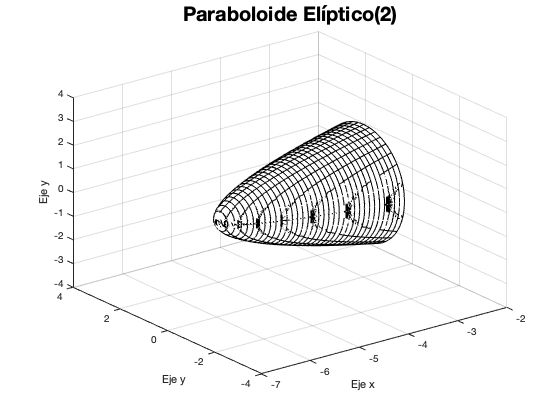

xlabel('Eje x')
ylabel('Eje y')
zlabel('Eje y')
xlim([-7 -2])
ylim([-4 4])
zlim([-4 4])
title('Paraboloide Elíptico(2)',"FontSize",20)
hold off
saveas(figure(4),'Paraboloide2','jpg')

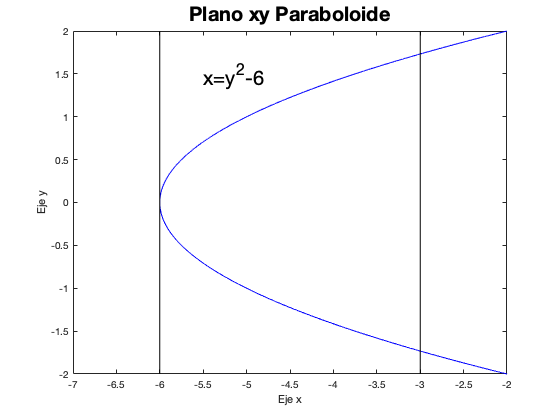

figure(5)
a=[-3 -3];
a1=[-6 -6];
b=[-2 2];
x6=-6:0.001:-2;
y6=(x6+6).^0.5;
y61=-(x6+6).^0.5;
plot(x6,y6,'b')
hold on
plot(x6,y61,'b')
plot(a,b,'k')
plot(a1,b,'k')
xlim([-7 -2])
ylim([-2 2])
xlabel('Eje x')
ylabel('Eje y')
title('Plano xy Paraboloide',"FontSize",20)
text(-5.5,1.5,'x=y^2-6',"FontSize",20)
hold off
saveas(figure(5),'ParaboloideXY','jpg')

figure(6)
a2=[-5 5];
b1=[2 2];
b2=[-2,-2];
plot(a2,b2,'b')
hold on
plot(a2,b1,'b')
ylim([-3 3])
xlim([-5 5])
b3=[-3 3];
a3=[(3)^0.5 (3)^0.5]

a3 =     1.7321    1.7321


a4=[-(3)^0.5 -(3)^0.5]

a4 =    -1.7321   -1.7321


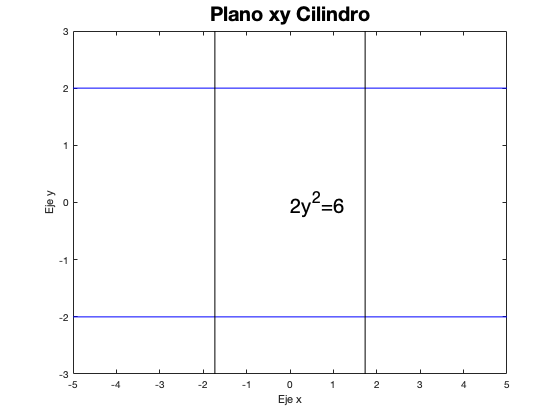

plot(a3,b3,'k')
plot(a4,b3,'k')
xlabel('Eje x')
ylabel('Eje y')
title('Plano xy Cilindro',"FontSize",20)
text(0,0,'2y^2=6',"FontSize",20)
hold off
saveas(figure(6),'CilindroXY','jpg')